# read & fit material index

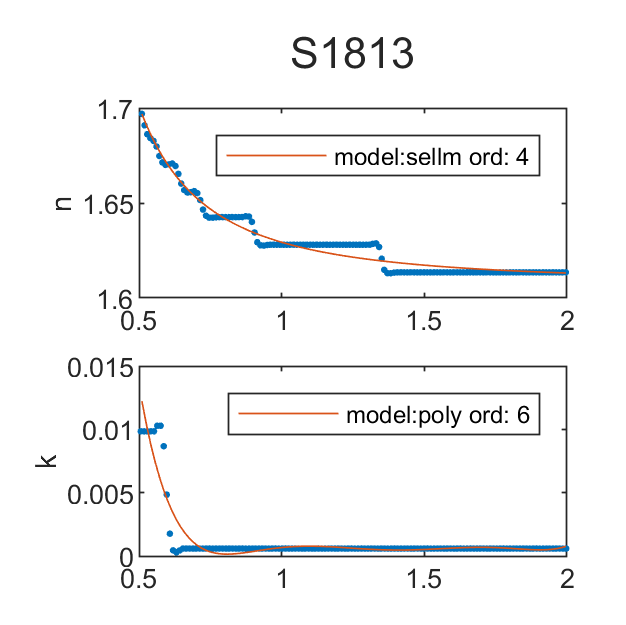

% refraction index objects
clear
mat_list = [];
warning('off','all')

% S1813
data = readmatrix("S1813.xlsx");
mat = Material('S1813');
fig = figure('Position',[0 0 250 250]);
lambda_n = data(:,1:2);
lambda_k = data(:,3:4);
mat_list = [mat_list,...
    dataFit(mat,lambda_n,lambda_k,'fig',fig,'w_range',[0.5,2])];

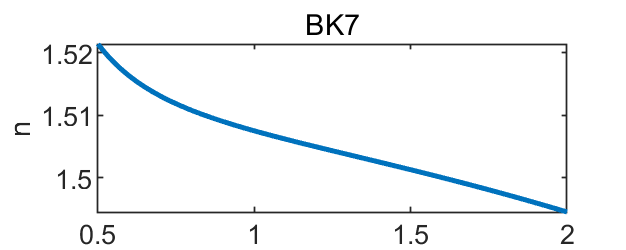


% BK7
coeffs = [1 1.03961212 0.00600069867 0.231792344 0.0200179144 1.01046945 103.560653];
mat = Material('BK7',coeffs);
mat.showN(figure('Position',[0 0 250 100]));

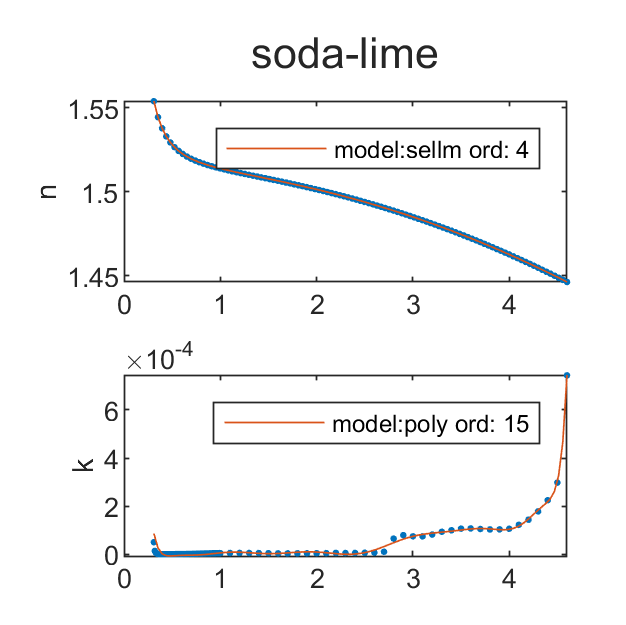

mat_list = [mat_list,mat];

% soda-lime
data = readmatrix("soda-lime.xlsx");
mat = Material('soda-lime');
fig = figure('Position',[0 0 250 250]);
lambda_n = data(:,1:2);
lambda_k = data(:,3:4);
mat_list = [mat_list,...
    dataFit(mat,lambda_n,lambda_k,...
    'k_order',15,'fig',fig)];

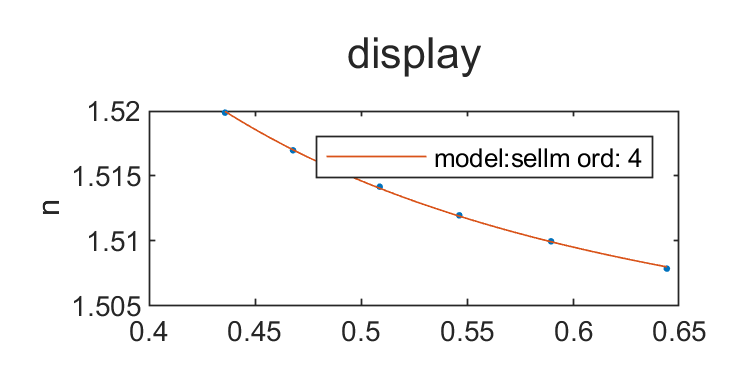


% display
data = readmatrix("display.xlsx");
mat = Material('display');
fig = figure('Position',[0 0 300 150]);
lambda_n = data;
mat_list = [mat_list,...
    dataFit(mat,lambda_n,'fig',fig)];


% save
save('material_list.mat','mat_list')


# Basic Init

clear
addpath 'Functions'
addpath 'Functions/reticolo_allege'
OptParm = Initialize();

## load material file

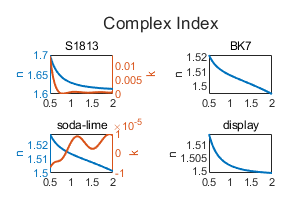

load('material_list.mat','mat_list')

f = figure('Position',[0 0 300 200]);
t = tiledlayout('flow','TileSpacing','compact');
title(t,'Complex Index')
for ii=1:length(mat_list)
    nexttile
    mat_list(ii).showIndex(f,[0.5,2])
end

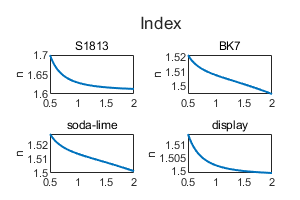

f = figure('Position',[0 0 300 200]);
t = tiledlayout('flow','TileSpacing','compact');
title(t,'Index')
for ii=1:length(mat_list)
    nexttile
    mat_list(ii).showN(f,[0.5,2])
end

## Basic Param

% 输入角度
incident_angle = 0;
OptParm.Input.Theta = incident_angle;
% 大致输出角度（会由于周期是像元整数而有出入）
target_angle = 25;
% 最小像素尺寸 (nm)
Pixel = 600;
OptParm.Geometry.Pixel = Pixel;
% 波长与偏振
OptParm.Input.Wavelength = [1500,1600];
Wavelength0 = mean(OptParm.Input.Wavelength);
OptParm.Input.Polarization = 'Both';
% 需要优化的级次
OptParm.Optimization.Target = 1;
% 厚度
OptParm.Geometry.Thickness = 3100; % Device layer thickness
% 折射率设置
OptParm.Geometry.Substrate = mat_list('soda-lime').getN(Wavelength0/1000); 
OptParm.Geometry.Device = mat_list('S1813').getN(Wavelength0/1000); 
OptParm.Geometry.Top = 1; % Refractive index of upper layer
disp(['n_sub = ' sprintf('%.2f ',OptParm.Geometry.Substrate)])

n_sub = 1.51 


disp(['n_device = ' sprintf('%.2f ',OptParm.Geometry.Device)])

n_device = 1.62 


disp(['n_top = ' sprintf('%.2f ',OptParm.Geometry.Top)])

n_top = 1.00 


% 利用光栅方程计算所需周期
Period = abs(OptParm.Optimization.Target(end))*Wavelength0/abs(sind(target_angle)-sind(incident_angle));
disp(['Beginning Period: ' sprintf('%.2f um; ',Period/1e3)])

Beginning Period: 3.67 um; 


ang = asind(abs(OptParm.Optimization.Target(end))*Wavelength0/(ceil(Period/Pixel)*Pixel) + sind(incident_angle));
disp(['Upper angle: ' sprintf('%.2f deg; ',ang)])

Upper angle: 21.66 deg; 


ang = asind(abs(OptParm.Optimization.Target(end))*Wavelength0/(floor(Period/Pixel)*Pixel) + sind(incident_angle));
disp(['Lower angle: ' sprintf('%.2f deg; ',ang)])

Lower angle: 25.50 deg; 


ang = asind(abs(OptParm.Optimization.Target(end))*Wavelength0/(round(Period/Pixel)*Pixel) + sind(incident_angle));
disp(['[Center angle]: ' sprintf('%.2f deg; ',ang)])

Center angle: 25.50 deg; 


Period = round(Period/Pixel)*Pixel;
disp(['[Period]: ' sprintf('%.2f um; ',Period/1e3)])

Period: 3.60 um; 


OptParm.Geometry.Period = Period;
OptParm.Geometry.PixelNum = round(Period/Pixel);
% 数值截断级次
NFourier = 20;
NFourier = ceil(NFourier*Period/Wavelength0);
OptParm.Simulation.Fourier = NFourier;
disp(['NFouriers: ' sprintf('%d  ',OptParm.Simulation.Fourier)])

NFouriers: 35  


% 台阶数
NLevel = 256;
OptParm.Geometry.Level = NLevel;
% 像元数目
N = round(Period/Pixel);
disp(['NPixels: ' sprintf('%d  ',N)])

NPixels: 6  


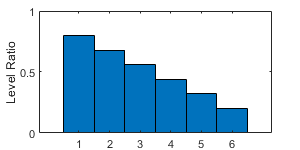

% 线性初值比例(0~1)
OptParm.Optimization.Start = fliplr((linspace(0.2,0.8,N)));
figure('Position',[0 0 300 150])
bar(OptParm.Optimization.Start,1)
ylabel('Level Ratio')
ylim([0 1])

% 暂存
save('Functions\BasicOptParm.mat','OptParm');

# Topology parameters

## Filter

% Blur radius [in grid units]
% [small intermittent filter]
OptParm.Optimization.Filter.BlurRadiusSmall = 5; 
% [First filter],[large intermittent filter]
OptParm.Optimization.Filter.BlurRadiusLarge = 60;
% [Second filter]
OptParm.Optimization.Filter.BlurRadius = 20; 

% Frequency of [small intermittent filter]
OptParm.Optimization.Filter.BlurSmallIter = 5; 
% Steps at the end of optimization which have no blurring
OptParm.Optimization.Filter.BlurSmallIterStop = 25; 
% Frequency of [large intermittent filter]
OptParm.Optimization.Filter.BlurLargeIter = 60; 
% Steps at the end of optimization which have no blurring
OptParm.Optimization.Filter.BlurLargeIterStop = 50; 

## Gradient & iterations

% Initial gradient step size
OptParm.Optimization.Gradient.StepSize = 0.1; 
% Multiplying factor that decreases step size each iteration
OptParm.Optimization.Gradient.StepDecline = 0.992; 

% Max iterations 
OptParm.Optimization.Iterations = 350; 

% Disable parfor warning messages
warning('off','MATLAB:mir_warning_maybe_uninitialized_temporary')

## Simulation

% 仿真x坐标每波长内网格数
OptParm.Simulation.Grid = 10; % Grid points per wavelength 
% 每个台阶内仿真层数
OptParm.Simulation.ZGrid = 3;

## Discretization

% Parameters for defining the binarization rate B. Smaller B is a
% less-sharp function, a large B will create a step function that cuts off 
% at the different values of N.

% Minimum value of B that is used after it is initialized. 
OptParm.Optimization.Binarize.Min = 1; 
% Maximum value of B
OptParm.Optimization.Binarize.Max = 50; 

% Iteration at which B is allowed to be nonzero.
OptParm.Optimization.Binarize.IterationStart = 1;
% Number of iterations during which B is kept constant before increasing (after it is initialized)
OptParm.Optimization.Binarize.IterationHold = 20;

## Robustness

% Start and End should be the same length. Each element represents a
% separate thread of the optimization at a different flat edge deviation in nm. 
% Starting edge deviation values
OptParm.Optimization.Robustness.StartDeviation = [-5 0 5]; 
% Ending edge deviation values
OptParm.Optimization.Robustness.EndDeviation = [-5 0 5];
% Iterations over which the thresholding parameter changes
OptParm.Optimization.Robustness.Ramp = 30; 
% Gradient weight for each robustness value
OptParm.Optimization.Robustness.Weights = [.5 1 .5]; 

## Start point

% Input pattern matrix as starting point. 
% Leave empty to generate random starting point
OptParm.Optimization.Start = []; 

% Ignored if starting point is already provided
% Grid size on which to create random Gaussians
OptParm.Optimization.RandomStart.Pitch = 10; 
% Average (0-1) 
OptParm.Optimization.RandomStart.Average = 0.6; 
% Standard deviation 
OptParm.Optimization.RandomStart.Sigma = 0.5; 

## Display

% 显示
% Display progress as console output
OptParm.Display.ShowText = 1; 
% Display current device geometry
OptParm.Display.PlotGeometry = 1;
% Plot device efficiency vs iteration
OptParm.Display.PlotEfficiency = 0; 
% gen GIF
OptParm.Display.GenGif = 0;
OptParm.Display.GifPrefix = '';

## Save

save('Functions\TopoOptParm.mat','OptParm');